# Non Cartesian Coordinates (1D)

clear, close all, clc
set_defaults()

The advantage of the dyadic notation ($\nabla$, $\nabla \cdot$,$\nabla \times$) is that it hides the coordinate system. Here we show that the same can be achived by the discrete operators. Currently we have only discretized one coordinate direction, but this already allows three different coordinate systems

- linear (1D)

- cylindrical radial (2D)

- spherical radial (3D)

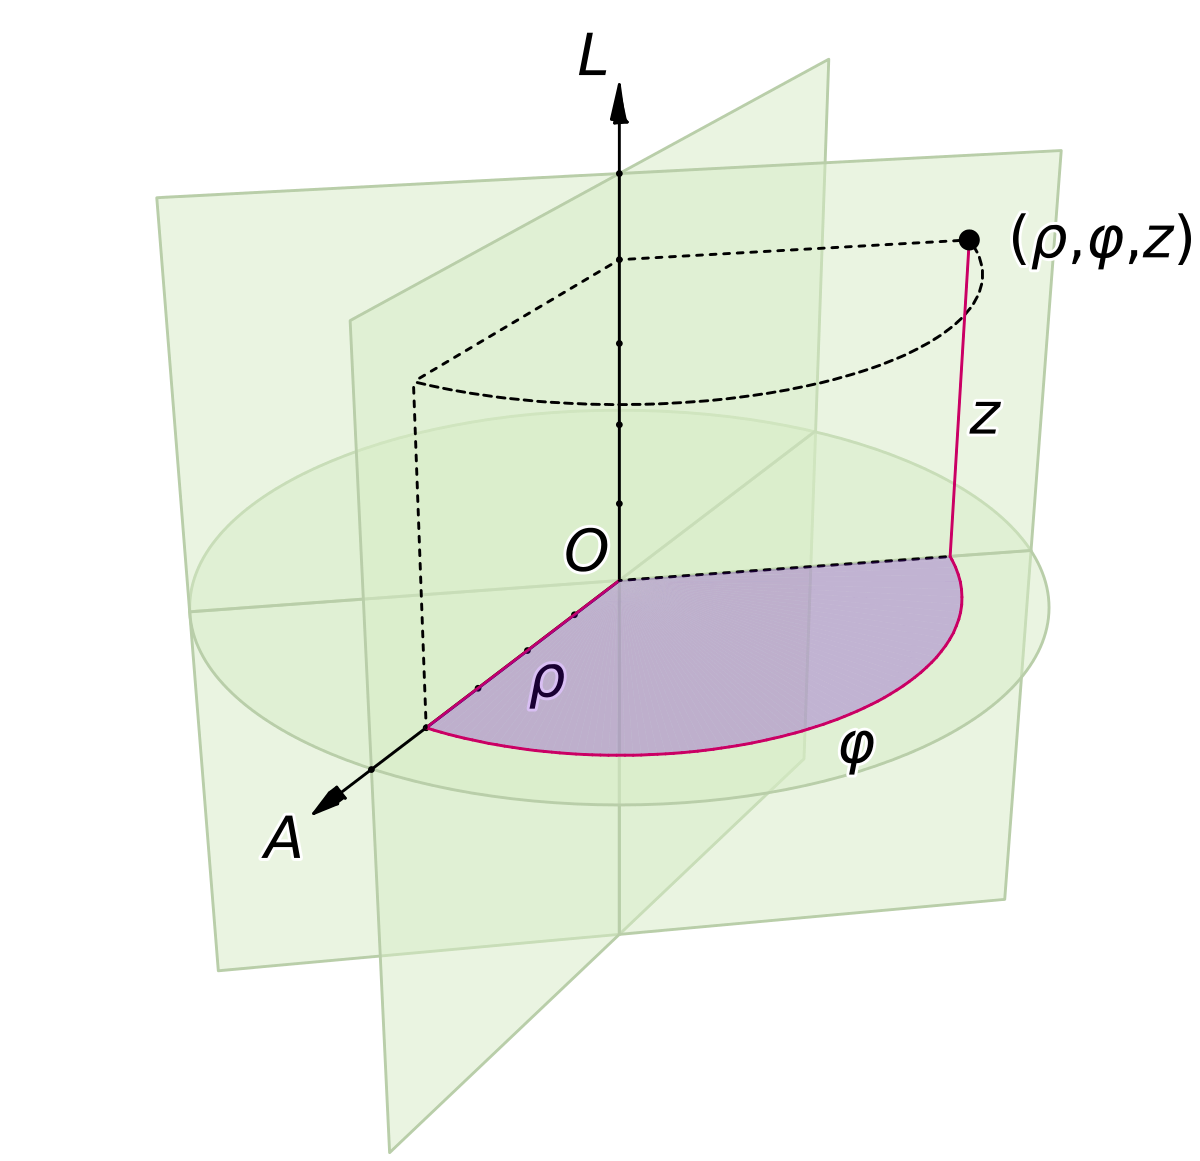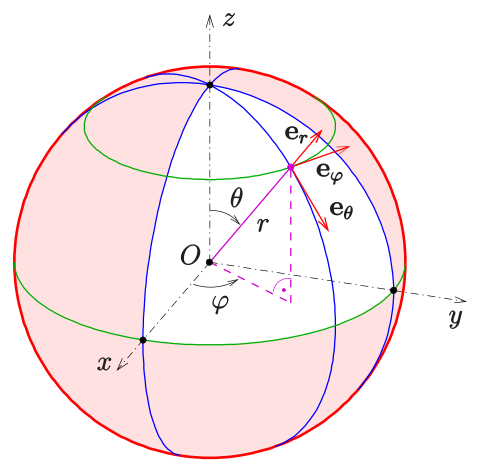

          Cylindrical Coordinates               Spherical Coordinates

The *gradient* is identical in all three coordinate systems: $\nabla = \frac{\mathrm{d}}{\mathrm{d}x}$

Here we also use the independent variable $\mathit{\mathbf{x}}$ to denote the **radial direction** in 2D and 3D.

In contrast to the gradient the *divergence* changes with the coordinate system

- linear (1D): $\nabla\cdot = \frac{\mathrm{d}}{\mathrm{d}x}$

- cylindrical radial (2D): $\nabla\cdot =\frac{1}{x} \frac{\mathrm{d}}{\mathrm{d}x}x $

- spherical radial (3D): $\nabla\cdot =\frac{1}{x^2} \frac{\mathrm{d}}{\mathrm{d}x}x^2$

Therefore we can write the general radial divergence in $d$ dimensions as: $\nabla\cdot =\frac{1}{x^{(d-1)}} \frac{\mathrm{d}}{\mathrm{d}x}x^{(d-1)}$

## Geometric interpretation of the radius terms

The key to the correct discretization is the geometric understanding of the two radius terms in the divergence. To facilitate this consider the equation for one-dimensional incompressible groundwater flow

in compact dyadic notation $-\nabla\cdot\left[K \nabla h\right] = f_s$  

or written explicitly in terms of the radial coordinate  $-\frac{\mathrm{d}}{\mathrm{d}x}\left[x^{(d-1)}K \frac{\mathrm{d}h}{\mathrm{d}x}\right] = x^{(d-1)}f_s$.

Note, here we have multiplied through by $x^{(d-1)}$, so that it is on the right hand side. In this form, the geometric origin of the two radius terms becomes clearer.

- The term $x^{(d-1)}\kappa$ suggests that this $x^{(d-1)}$ represents that growth of the interfacial area with increasing radius, because $\kappa
$ is associate with the flux. This radius term should therefore evaluated at the cell faces `Grid.xf`.

- The term $x^{(d-1)}f_s$ suggests that this $x^{(d-1)}$ represents the growth of the volume with increasing radius, because $f_s$ is the volumetic source term. This radius term should therefore be evaluated at the cell centers `Grid.xc`.

## Test problem 1: Steady state flow near a well

Flow near a groundwater well is a common problem in hydrogeology. The well typically has a casing, i.e., a steal tube, that prevents water leakage from formations above the aquifer. In the aquifer the casing is perforated, i.e., has holes, to allow groundwater to enter or exit the well. The near well flow depends on the distribution of perforations in the aquifer inteval of the well:

- Well is **uniformly** perforated over the entire aquifer interval (left) for that water can flow acriss the entire height so that the flow has **cylindrical** geometry.

- Well is only** locally** perforated (right). If this local perforation is in the center of the aquifer interval the near well flow has **spherical** geometry.

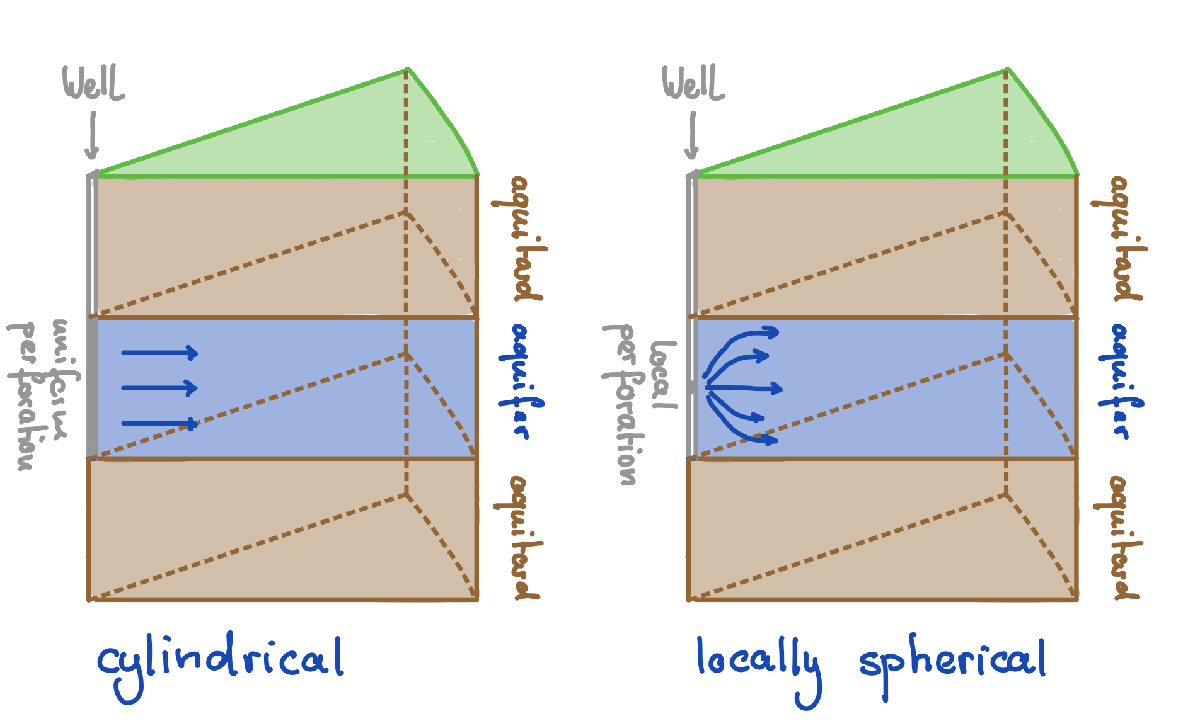

The cylindrical case is imilar to the injection well problem we considered in Lecture 3. Except here we prescribe the head at the well instead of the flow rate.

The problem statement for the near well flow is given by

PDE: $-\frac{1}{x^{(d-1)}}\frac{\mathrm{d}}{\mathrm{d}x}\left[x^{(d-1)}K \frac{\mathrm{d}h}{\mathrm{d}x}\right] = 0$  for  $x \in \left[x_{min},\,x_{max}\right]$

with the Dirichlet BC's $h(x_{min}) = h_1$ and $h(x_{max}) = h_2$, where $x_{min} > 0$.

The analytic solutions for the head are given by

- linear (1D): $h(x) = h_1 + \frac{h_2-h_1}{x_{max}-x_{min}}(x-x_{min})$

- clylindrical (2D): $h(x) = h_1 + (h_2-h_1)\frac{\ln(x/x_{min})}{\ln(x_{max}/x_{min})}$

- spherical (3D): $h(x) = h_1 + \frac{h_2-h_1}{\frac{1}{x_{max}}-\frac{1}{x_{min}}}\left(\frac{1}{x}-\frac{1}{x_{min}}\right)$

The corresponding fluxes are given by

- linear (1D): $q(x)=-K\frac{h_2-h_1}{x_{max}-x_{min}}$

- cylindrical (2D): $q(x) = -K \frac{h_2-h_1}{\ln\left(\frac{x_{max}}{x_{min}}\right)}\frac{1}{x}$

- spherical (3D): $q(x) = K\frac{h_2-h_1}{\frac{1}{x_{max}}-\frac{1}{x_{min}}} \frac{1}{x^2}$

We assume the folowing values, we use the ana

cm2m = 1/100;        % cm to m conversion
yr2s = 365*24*60^2;  % yr to s conversion

xmin = .5;   % well radius
xmax = 100;  % domain radius
h2 = 1;    % far-field head
Qw = 1;    % well flow rate
H = 1;     % aquifer thickness
K = 1;     % hydraulic conductivity
Aw = 2*pi*xmin*H; % wellbore area
% rlim = [param.rw,param.r0];

ha = @(x) h2 - Qw/2/pi/H/K * log(x/xmin);

Here we use the anaytic solution from class to compute the head at the well from the flow rate

h1 = ha(xmin);
h2 = 0;
xana = linspace(xmin-1e-2,xmax,1e3);
h1d_ana = @(x) h1 + (h2-h1)/(xmax-xmin)*(x-xmin);
h2d_ana = @(x) h1 + (h2-h1)*log(x/xmin)/log(xmax/xmin);
h3d_ana = @(x) h1 + (h2-h1)/(1/xmax-1/xmin)*(1./x-1/xmin);

q1d_ana = @(x) -K*(h2-h1)/(xmax-xmin)+x*0;
q2d_ana = @(x) -K*(h2-h1)/log(xmax/xmin)*1./x;
q3d_ana = @(x) K*(h2-h1)/(1/xmax-1/xmin)*1./(x.^2);

## Discretization of the divergence

The radial component of the discrete divergence matrix in cylindital and spherical geometry can therefore be obtained as follows

Grid.xmin = xmin; Grid.xmax = xmax; Grid.Nx = 35;
Grid = build_grid(Grid);
[D,G,C,I,M] = build_ops(Grid);
fs = spalloc(Grid.Nx,1,0);

% General radial coordinate system
Rinv = @(d) spdiags(1./Grid.xc.^(d-1),0,Grid.Nx,Grid.Nx);
R = @(d) spdiags(Grid.xf.^(d-1),0,Grid.Nfx,Grid.Nfx);
D = @(d) Rinv(d)*D*R(d);
L = @(d) -D(d)*K*G;
flux = @(h) -K*G*h;
L1 = L(1); res1d = @(h,cell) L1(cell,:)*h - fs(cell);
L2 = L(2); res2d = @(h,cell) L2(cell,:)*h - fs(cell);
L3 = L(3); res3d = @(h,cell) L3(cell,:)*h - fs(cell);

Set Dirichlet boundary conditions

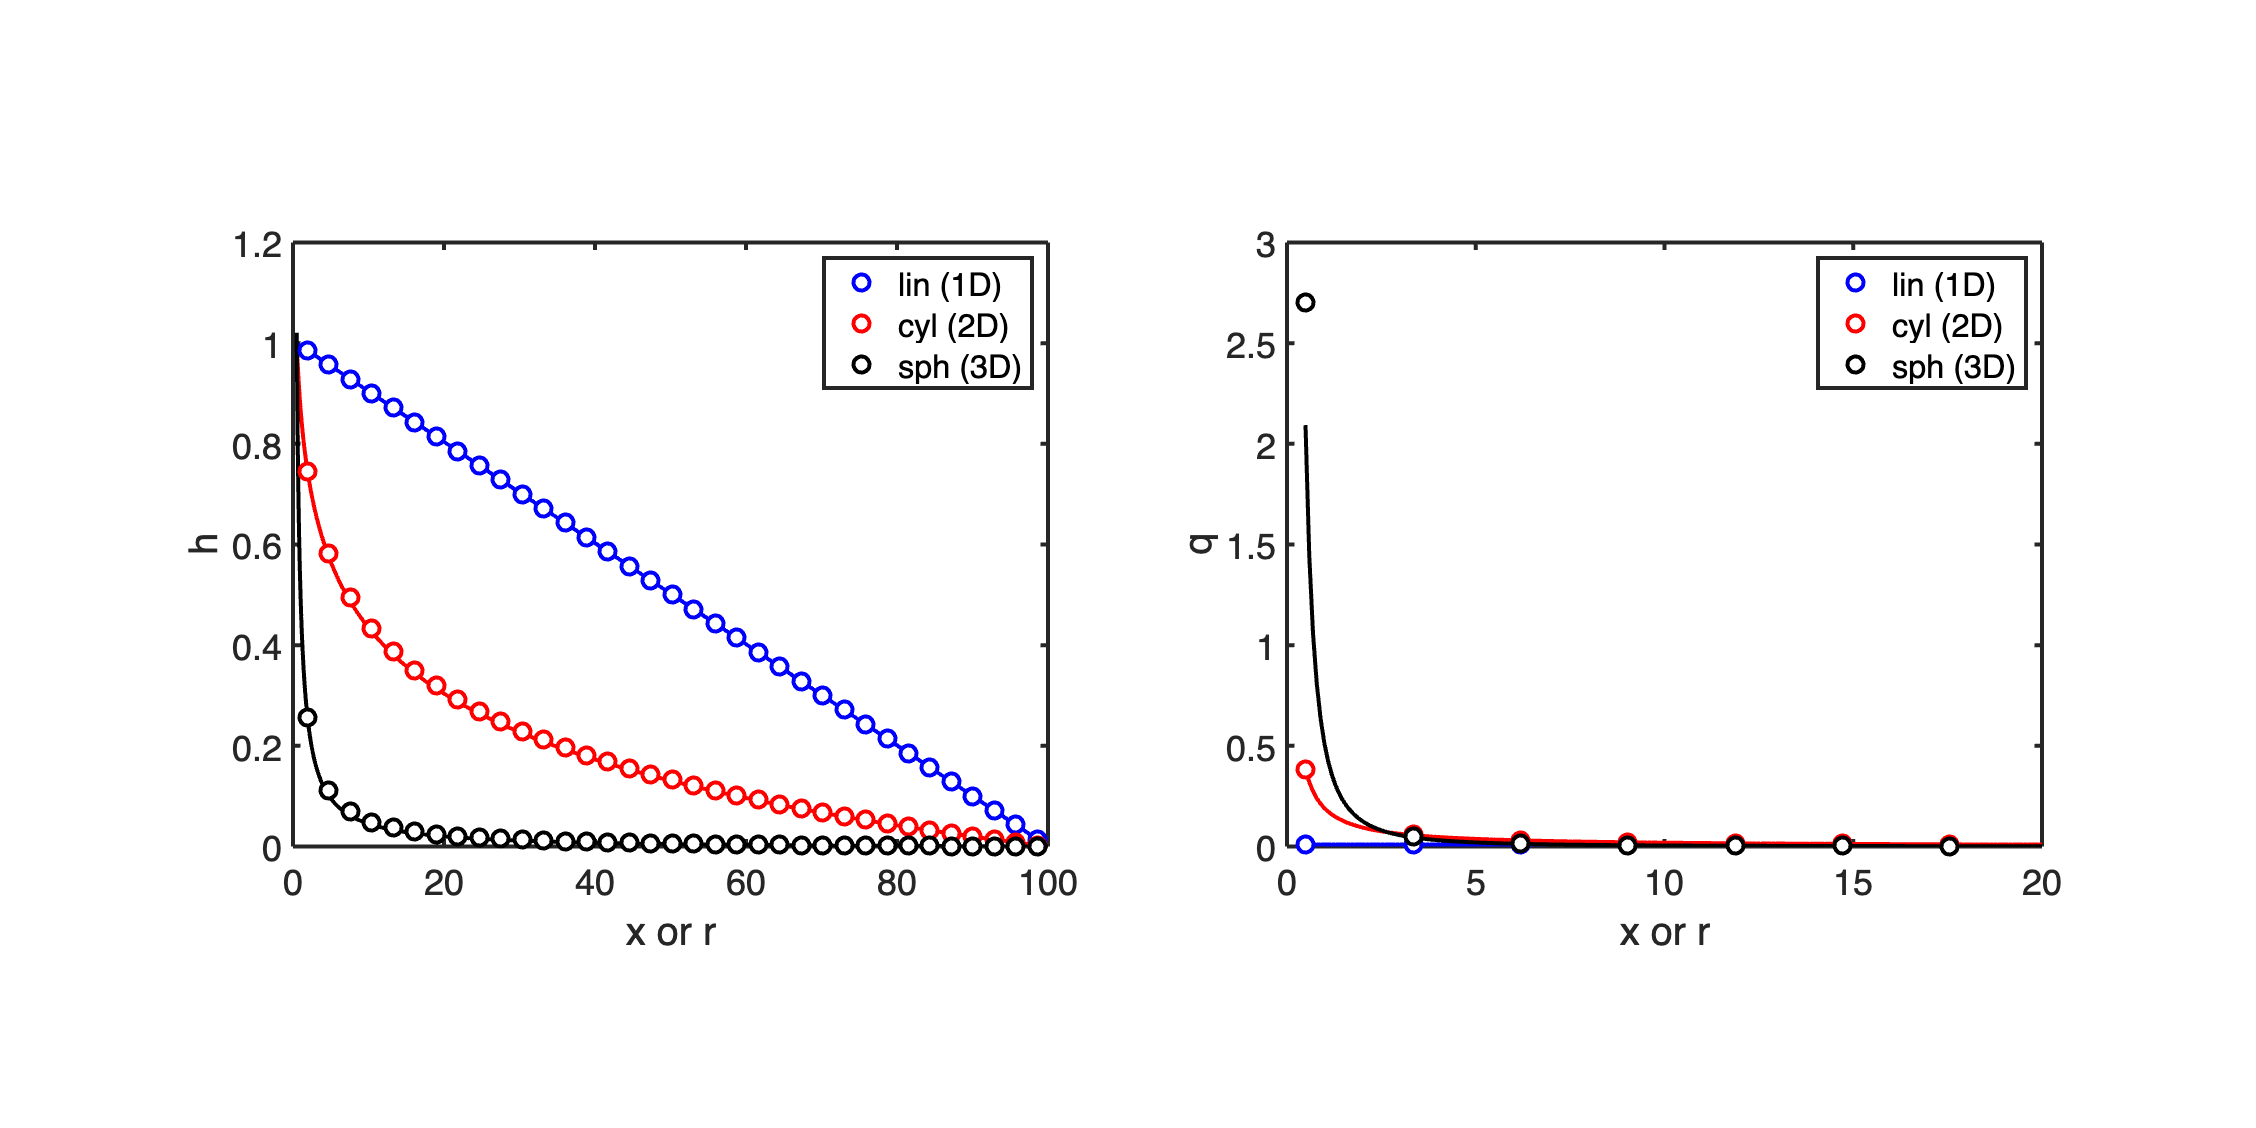

BC.dof_dir   = [Grid.dof_xmin;Grid.dof_xmax];
BC.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
BC.dof_neu   = [];
BC.dof_f_neu = [];

% 1D - linear
BC.g = h1d_ana(Grid.xc(BC.dof_dir));
[B,N,fn] = build_bnd(BC,Grid,I);
h1d = solve_lbvp(L(1),fs+fn,B,BC.g,N);
q1d = comp_flux_gen(flux,res1d,h1d,Grid,BC);

% 2D - cylindrical
Grid.geom = 'cylindrical_r'; Grid = build_grid(Grid); % update Grid.A and Grid.V
BC.g = h2d_ana(Grid.xc(BC.dof_dir));
h2d = solve_lbvp(L(2),fs+fn,B,BC.g,N);
q2d = comp_flux_gen(flux,res2d,h2d,Grid,BC);

% 3D - spherical
Grid.geom = 'spherical_r'; Grid = build_grid(Grid); % update Grid.A and Grid.V
BC.g = h3d_ana(Grid.xc(BC.dof_dir));
h3d = solve_lbvp(L(3),fs+fn,B,BC.g,N);
q3d = comp_flux_gen(flux,res3d,h3d,Grid,BC);

figure('position',[10 10 1200 600])
subplot 121
plot(xana,h1d_ana(xana),'b-'), hold on
plot(xana,h2d_ana(xana),'r-')
plot(xana,h3d_ana(xana),'k-')
p1 = plot(Grid.xc,h1d,'bo','markerfacecolor','w','markersize',8); hold on
p2 = plot(Grid.xc,h2d,'ro','markerfacecolor','w','markersize',8);
p3 = plot(Grid.xc,h3d,'ko','markerfacecolor','w','markersize',8);
xlabel 'x or r', ylabel 'h'
pbaspect([1 .8 1])
legend([p1 p2 p3],'lin (1D)','cyl (2D)','sph (3D)')

subplot 122
plot(xana,q1d_ana(xana),'b'), hold on
plot(xana,q2d_ana(xana),'r')
plot(xana,q3d_ana(xana),'k')
l1 = plot(Grid.xf,q1d,'bo','markerfacecolor','w','markersize',8);
l2 = plot(Grid.xf,q2d,'ro','markerfacecolor','w','markersize',8);
l3 = plot(Grid.xf,q3d,'ko','markerfacecolor','w','markersize',8);
xlabel 'x or r', ylabel 'q'
xlim([0 20])
pbaspect([1 .8 1])
legend([l1 l2 l3],'lin (1D)','cyl (2D)','sph (3D)')

If we set the boundary conditions using the analytical solution at the cell centers, the numerical solution matches the anaytic solution very well. Our discrete divergence in cylindrical and spherical radial coordinates is therefore correct.

Note how the head decays more rapidly with distance in higher coordinates. This is because the fluid flow is distributed into shells of in creasing volume in 2D and 3D. 

## Test problem 2: Cylindical aquifer beneath a (near) circular island

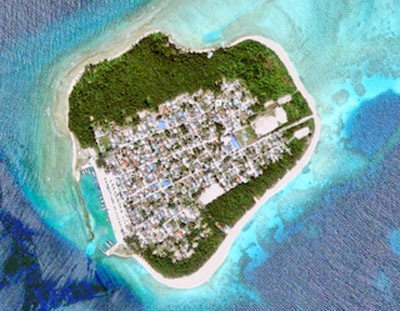   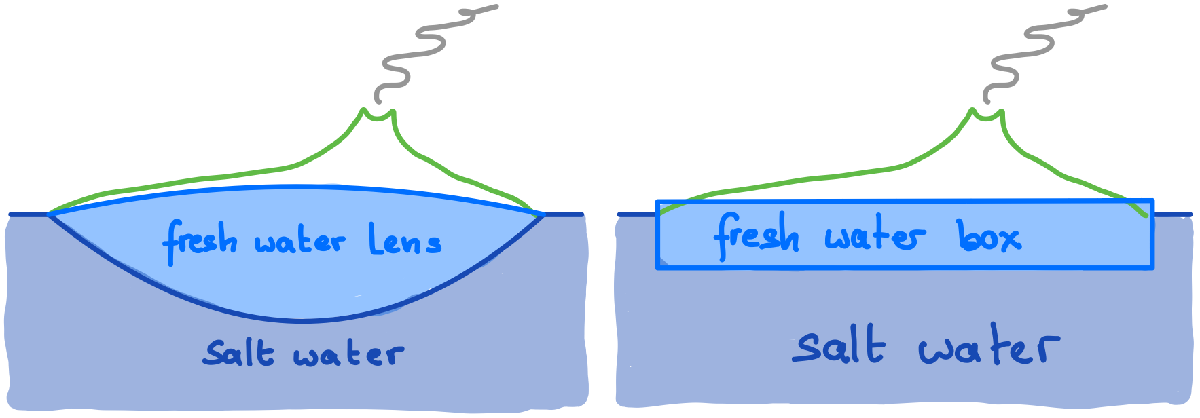

The island of Ihavandhoo (Maledives) has a mean diameter of *R* = 435 m, an annual rainfall of $q_p$=1779 mm and a fresh water lens of approximately *b* = 7 m thickness. Inhabitant rely on this groundwater and a small desalination plant for all their ptable water needs. The real problem of groundwater on islands is complicated because the aquifer is typically unconfined and the fresh water interacts with the denser sea water beneat to form a lense that thins towards the edges of the island. Here we will simply assume that the aquifer is confined and has a rectangular cross-section with average height, *b*. The shallow aquifer model is then given by 

To compute the steady temerature profile in an asteroid of radius, $R$, heated uniformly by radioactive decay we solve

$-\frac{1}{x}\frac{\mathrm{d}}{\mathrm{d}x}\left[x\,b K \frac{\mathrm{d}h}{\mathrm{d}x}\right] = q_p$  for  $x \in \left[0,\,R\right]$

with the Dirichlet BC $h(R) = 0$ and the natural (no flow) BC at the center. Note that including the origin, $r=0$, is not a problem because the term $1/x^{1-d}$ is evaluated at cell centers!

The analytic solution for the head of the island aquifer is given by


$$h(x) = \frac{q_p}{4bK}\left(R^2-r^2\right)$$


The fluid flux in the aquifer is given by

$q(x) = \frac{q_p}{2b}r$.

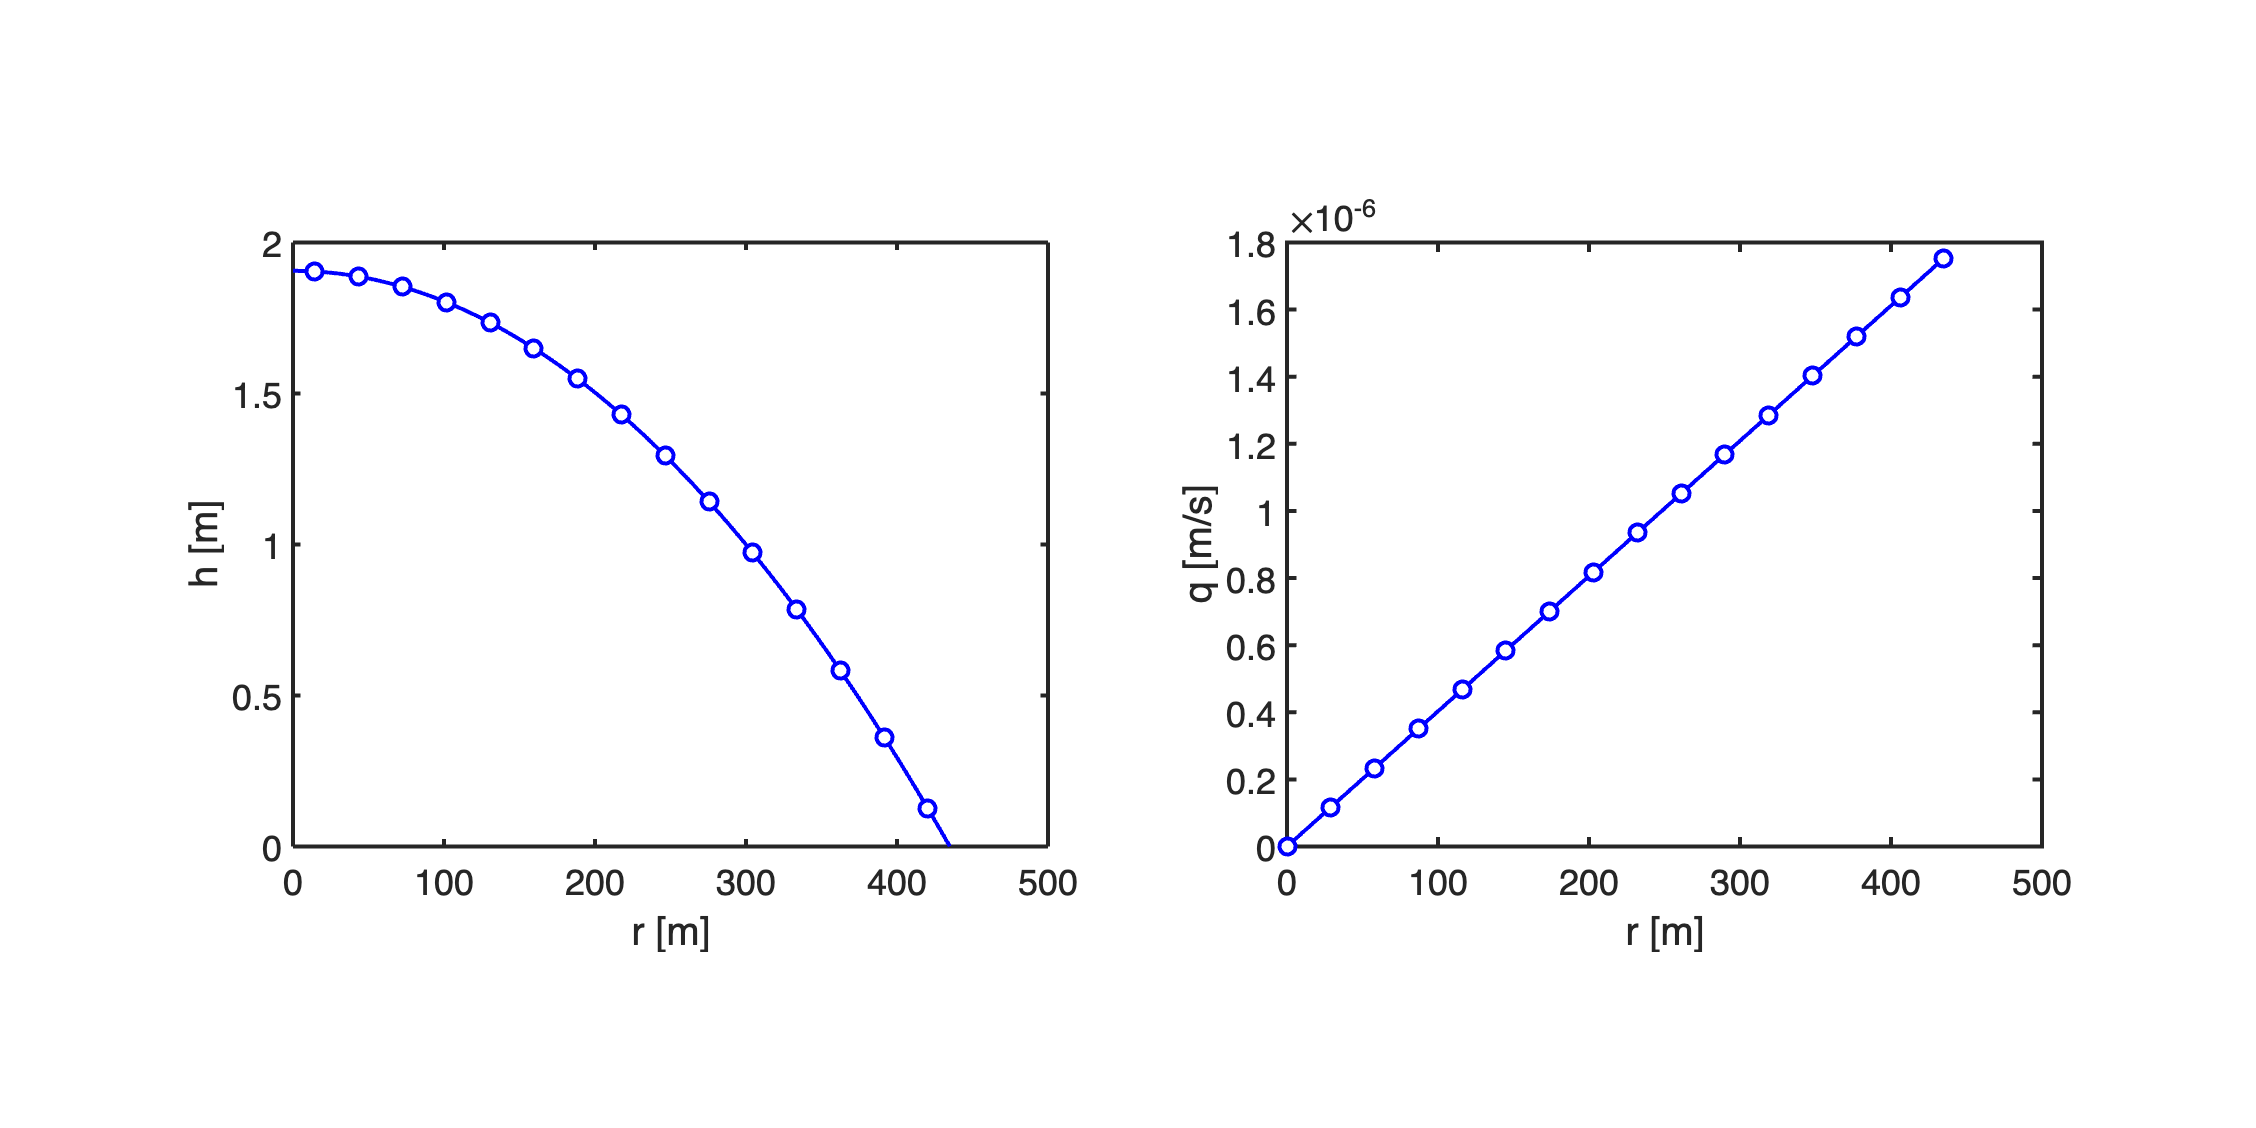

R = 435;             % Island radius [m]
K =2e-2*cm2m;        % Hydraulic conductivity [m/s]
b = 7;               % freash water lens thickness [m]
qp = 177.9*cm2m/yr2s;  % Average annual precipitation [m3/m2/s]

% Analytical solution
xa_island = linspace(0,R,1e3);
ha_island = @(x) qp/(4*b*K)*(R^2-x.^2);
qa_island = @(x) qp/(2*b)*x;

% Numerical solution
Grid.xmin = 0; Grid.xmax = 435; Grid.Nx = 15;
Grid.geom = 'cylindrical_r'; 
Grid = build_grid(Grid);
[D,G,C,I,M] = build_ops(Grid);
fs = qp/b*ones(Grid.Nx,1);
L = -D*K*G;
flux_island = @(h) -K*G*h;
res_island = @(h,cell) L(cell,:)*h-fs(cell);

% Set boundary conditions
BC.dof_dir = [Grid.dof_xmax];
BC.dof_f_dir = [Grid.dof_f_xmax];
BC.g = ha_island(Grid.xc(BC.dof_dir));
BC.dof_neu = [];
BC.dof_f_neu = [];
BC.qb = [];
[B,N,fn] = build_bnd(BC,Grid,I);

h_island = solve_lbvp(L,fs+fn,B,BC.g,N);
q_island = comp_flux_gen(flux_island,res_island,h_island,Grid,BC);



figure('position',[10 10 1200 600])
subplot 121
plot(xa_island,ha_island(xa_island),'b-'), hold on
plot(Grid.xc,h_island,'bo','markerfacecolor','w','markersize',8)
pbaspect([1 .8 1])
xlabel 'r [m]', ylabel 'h [m]'

subplot 122
plot(xa_island,qa_island(xa_island),'b-'), hold on
plot(Grid.xf,q_island,'bo','markerfacecolor','w','markersize',8), hold on
pbaspect([1 .8 1])
xlabel 'r [m]', ylabel 'q [m/s]'

# Auxillary functions

## set_defaults()

function [] = set_defaults()
    set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end